DOA = FunctionsOfDOA();
coef = 0.5; % unit distance between sensors divided by the wavelength of the signal

input = [0 3 3];        % [nested_array M1 M2]
% input = [1 2 3];      % [coprime_array M1 M2]
% input = [2 4 3];      % [super_nested_array M1 M2]
% input = [3 4 4 3];    % [augmented_nested_array_1 M1 M2 L1]
% input = [4 7 4];      % [augmented_nested_array_2 M1 M2]
% input = [5 3 3];        % [nested_array_v2 M1 M2]

if input(1) ~= 1
    M = sum(input(2:3))                                     % # of sensors
else
    M = 2 * input(2) - 1 + input(3)
end

M = 6

sensor_locations = DOA.Sensor_Locations(input)                  % sensor locations

sensor_locations =      1     2     3     4     8    12


sensor_placement = DOA.Sensor_Placement(sensor_locations)       % sensor places (in order to visualize the array)

sensor_placement =      1     1     1     1     0     0     0     1     0     0     0     1


diff_coarray = DOA.Diff_Coarray(sensor_placement)               % difference coarray

diff_coarray =      1     1     1     1     1     1     1     2     1     2     3     6     3     2     1     2     1     1     1     1     1     1     1


uDOF = DOA.Uniform_Degrees_Of_Freedom(diff_coarray)             % uniform degrees of freedom

uDOF = 23

LuDOF = DOA.One_Side_Uniform_Degrees_Of_Freedom(diff_coarray)   % one side uniform degrees of freedom

LuDOF = 11

Now, let's use the calculated sensor_locations to compute the array pattern

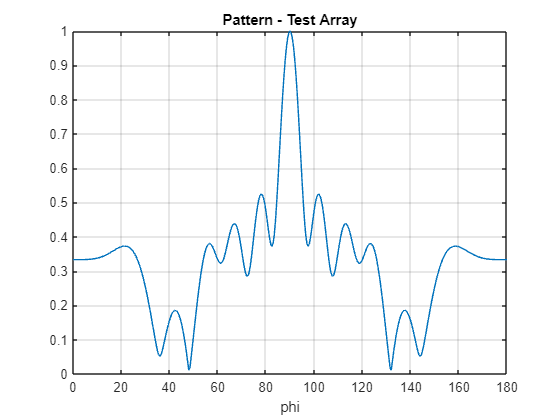

DOA.Array_Pattern(sensor_locations, coef)

and solve an example DOA problem

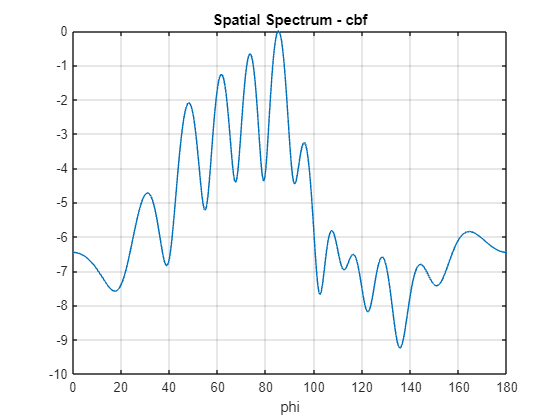

% doa = sort(randi(179, 1, 2));
% doa = [50 150];
doa = 90 - asind(0:0.2:0.6) - 5;                            % source angles
snapshots = 1000;                                           % # of snapshots
SNR_dB = 0;                                                 % signal to noise ratio in decibels
C = DOA.Mutual_Coupling(100, 0.1, M, sensor_locations);         % mutual coupling

DOA.Spatial_Spectrum(M, sensor_locations, doa, snapshots, SNR_dB, coef, "cbf", C);

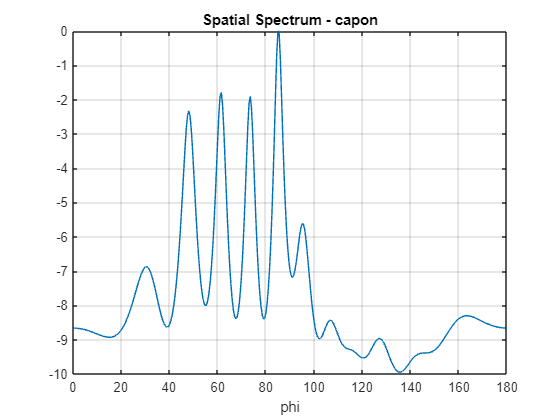

DOA.Spatial_Spectrum(M, sensor_locations, doa, snapshots, SNR_dB, coef, "capon", C);

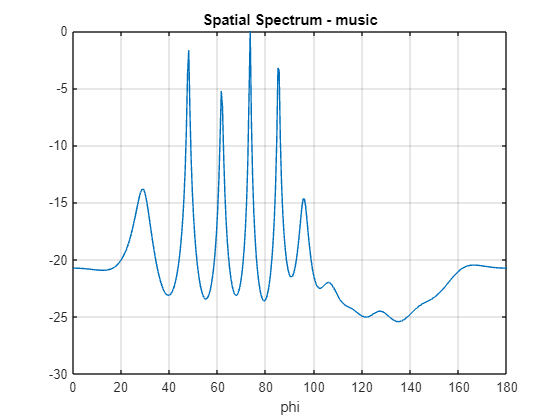

DOA.Spatial_Spectrum(M, sensor_locations, doa, snapshots, SNR_dB, coef, "music", C);

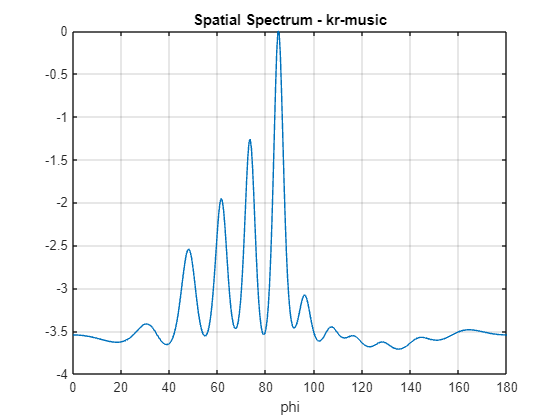

DOA.Spatial_Spectrum(M, sensor_locations, doa, snapshots, SNR_dB, coef, "kr-music", C);

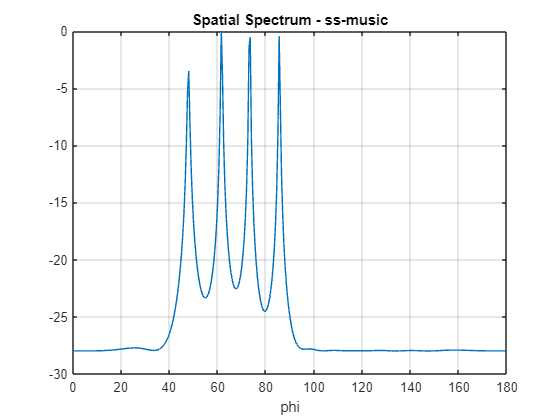

DOA.Spatial_Spectrum(M, sensor_locations, doa, snapshots, SNR_dB, coef, "ss-music", C);

#### Testing Area

Spatial Smoothing is tried here.

n = length(doa);
N = 1000;
SNR = 0;
M_v = sensor_locations(end);

s = zeros(n, N);
theta = 180 * rand(n, 1);
for i = 1:n
    s(i, :) = exp(1i * 2 * pi * coef * (0:N-1) * cosd(theta(i)));
end
v = (1 / 10^(SNR/10)) * (1/sqrt(2)) * (randn(M, N) + 1i * randn(M, N));

A = zeros(M, n);
for i = 1:n
    A(:, i) = exp(1i * 2 * pi * coef * (sensor_locations - 1).' * cosd(doa(i)));
end

y = C * A * s + v;
Ry = (1 / N) * (y * y');
z = Ry(:);

A_d = DOA.khatri_rao(conj(A), A);
p = zeros(n, 1);
for i = 1:n
    p(i) = var(s(i, :));
end

one_v = eye(M); one_v = one_v(:);
sigma_v = 0;
for i = 1:M
    sigma_v = sigma_v + (1 / M) * var(v(i, :));
end

z_ = A_d * p + sigma_v * one_v;

A1 = DOA.Rearrange_According_to_Sensor_Locations(A_d, sensor_locations);
e = zeros(2 * M_v - 1, 1); e(M_v) = 1;

z1 = A1 * p + sigma_v * e;
R_z1 = zeros(M_v);
for i = 1:M_v
    z1_i = z1(i:i + M_v - 1);
    R_z1 = R_z1 + (1 / M_v) * (z1_i * z1_i');
end
R_z1

R_z1 =    6.1639 + 0.0000i   1.8972 - 4.6528i  -1.4923 - 1.4853i   0.6092 - 0.2957i  -0.0507 - 1.5906i  -0.4447 - 0.1774i   0.8067 - 0.8586i  -0.5363 - 1.3601i   0.4331 - 0.2498i   0.8185 - 3.4781i  -4.6654 - 3.4898i  -4.8365 + 2.9306i
   1.8972 + 4.6528i   5.9032 + 0.0000i   1.5746 - 3.8462i  -0.8477 - 0.8315i   1.0084 - 0.4175i   0.0092 - 1.3699i   0.0189 - 0.0264i   0.9547 - 0.9690i  -0.2810 - 1.0016i   1.2675 - 0.3789i   0.9910 - 4.1295i  -4.6654 - 3.4898i
  -1.4923 + 1.4853i   1.5746 + 3.8462i   4.7508 + 0.0000i   1.2242 - 3.0425i  -0.7036 - 0.6227i   0.7734 - 0.2558i   0.0447 - 1.0071i   0.0315 - 0.0009i   0.7301 - 0.6522i  -0.0563 - 0.6233i   1.2675 - 0.3789i   0.8185 - 3.4781i
   0.6092 + 0.2957i  -0.8477 + 0.8315i   1.2242 + 3.0425i   4.2516 + 0.0000i   1.1826 - 3.0140i  -0.8771 - 0.7382i   0.6572 - 0.1798i   0.0381 - 1.0992i  -0.1611 - 0.0547i   0.7301 - 0.6522i  -0.2810 - 1.0016i   0.4331 - 0.2498i
  -0.0507 + 1.5906i   1.0084 + 0.4175i  -0.7036 + 0.6227i   1.1826 + 3.0140i 

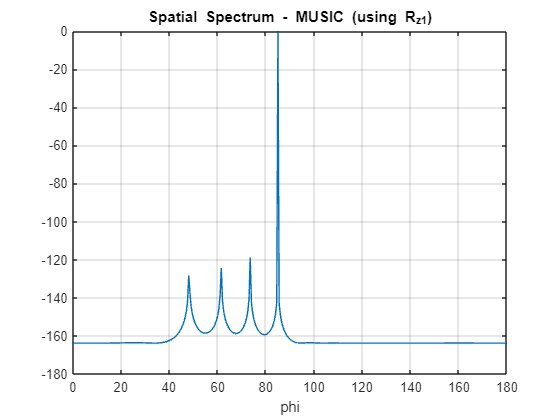

DOA.MUSIC(n, coef, R_z1, 1);

doa

doa =    85.0000   73.4630   61.4218   48.1301


z1 = DOA.Rearrange_According_to_Sensor_Locations(z, sensor_locations);
R_z1 = zeros(M_v);
for i = 1:M_v
    z1_i = z1(i:i + M_v - 1);
    R_z1 = R_z1 + (1 / M_v) * (z1_i * z1_i');
end
R_z1

R_z1 =    8.9251 + 0.0000i   5.2521 - 5.4045i   1.1975 - 3.8388i   1.9857 - 2.8299i   1.2232 - 3.3472i   0.7263 - 2.7366i   1.1888 - 3.5188i  -0.1393 - 3.9528i  -0.3841 - 3.5194i  -1.1272 - 5.9630i  -6.7433 - 5.1957i  -7.4924 + 1.5061i
   5.2521 + 5.4045i   9.0093 + 0.0000i   4.9155 - 4.3617i   2.1869 - 2.6978i   2.4966 - 2.3933i   1.6636 - 2.8812i   1.6692 - 2.4638i   1.8132 - 3.6818i   0.5196 - 4.0572i   1.0718 - 3.9729i  -0.8547 - 7.0895i  -6.7433 - 5.1957i
   1.1975 + 3.8388i   4.9155 + 4.3617i   7.3162 + 0.0000i   4.3112 - 3.1663i   2.0206 - 2.2932i   2.3041 - 1.8840i   1.8679 - 2.1513i   1.9621 - 2.1451i   2.0722 - 3.1762i   1.1456 - 3.3448i   1.0718 - 3.9729i  -1.1272 - 5.9630i
   1.9857 + 2.8299i   2.1869 + 2.6978i   4.3112 + 3.1663i   6.7878 + 0.0000i   4.2748 - 3.2172i   1.8348 - 2.2419i   2.2444 - 1.6632i   1.8905 - 2.1001i   1.8063 - 2.0012i   2.0722 - 3.1762i   0.5196 - 4.0572i  -0.3841 - 3.5194i
   1.2232 + 3.3472i   2.4966 + 2.3933i   2.0206 + 2.2932i   4.2748 + 3.2172i 

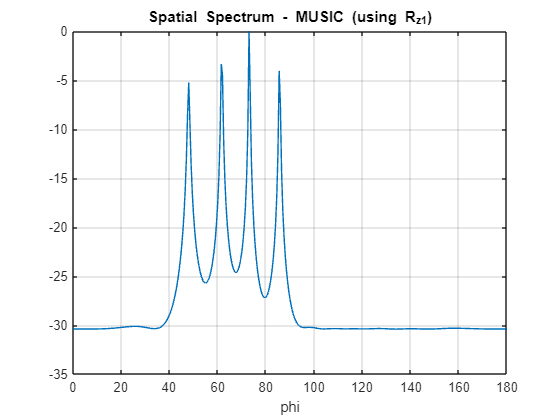

DOA.MUSIC(n, coef, R_z1, 1);